## Compute sea level averaged over the Pacific basin

load Module2_large
[nt,nlat,nlon] = size(ALT.sl);

## For each time, compute the spatially averaged sea level

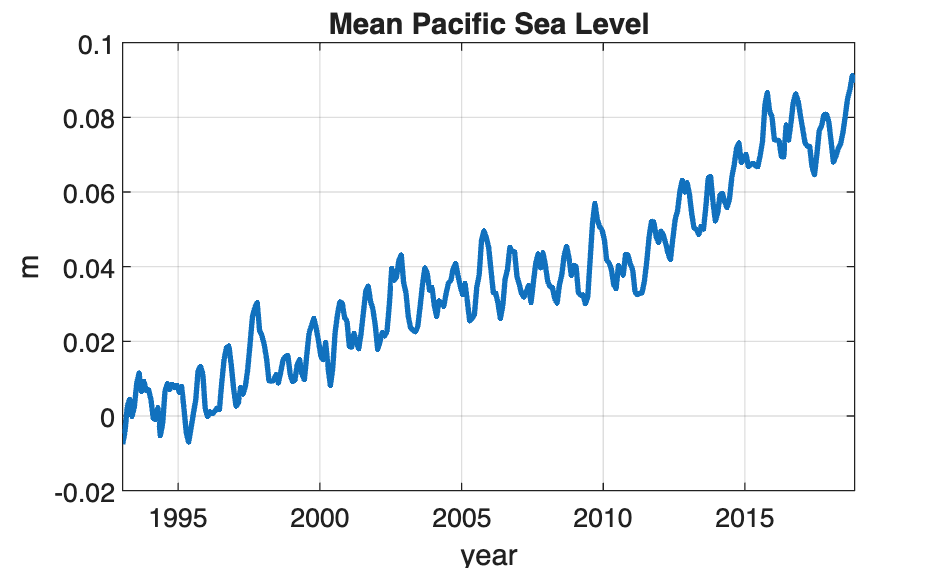

sl_avg = NaN(nt,1);
for j = 1:nt
    sl = squeeze(ALT.sl(j,:,:));
    sl_avg(j) = mean(sl(:),'omitnan');
end
figure (1)
clf
plot(ALT.t,sl_avg,'LineWidth',2)
ylabel('m')
xlabel('year')
title('Mean Pacific Sea Level')
grid on

## Remove the seasonal cycle

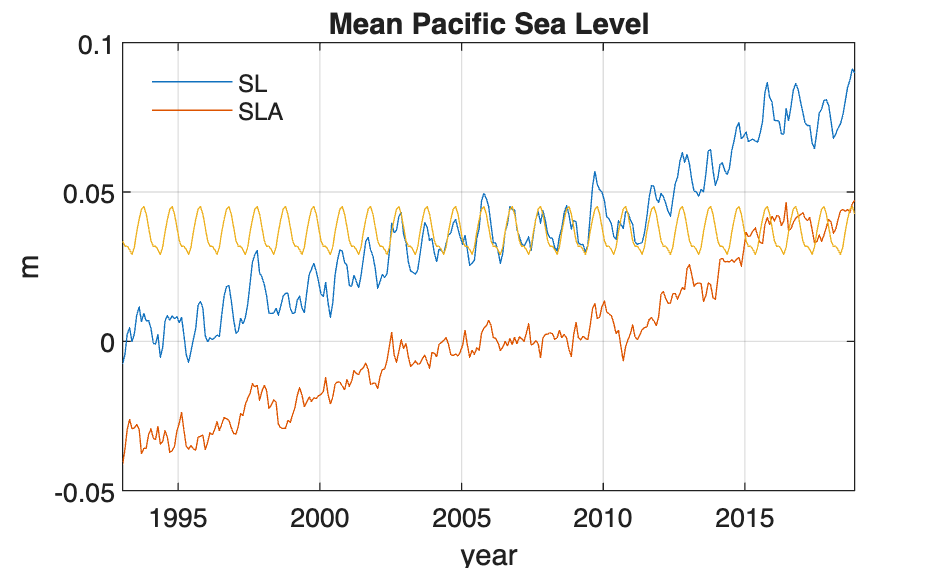

[yr,mo,dy] = datevec(ALT.t);
sla_avg = sl_avg;
sla_sea = NaN(12,1);
for j = 1:12
    sla_sea(j) = mean(sl_avg(mo==j));
    sla_avg(mo==j) = sla_avg(mo==j)-sla_sea(j);
end
figure (2)
clf
plot(ALT.t,sl_avg,ALT.t,sla_avg,ALT.t,sl_avg-sla_avg)
ylabel('m')
xlabel('year')
title('Mean Pacific Sea Level')
legend('SL','SLA','Location','northwest')
legend('boxoff')
grid on

## Compute and remove trend

tt = datenum(ALT.t);
tt = tt - mean(tt);
P = polyfit(tt,sla_avg,1);
SLR_mm_yr = P(1)*1000*365.25;
formatspec = 'Pacific sea level trend is %.2f mm/yr';
display(sprintf(formatspec,SLR_mm_yr))

Pacific sea level trend is 2.96 mm/yr


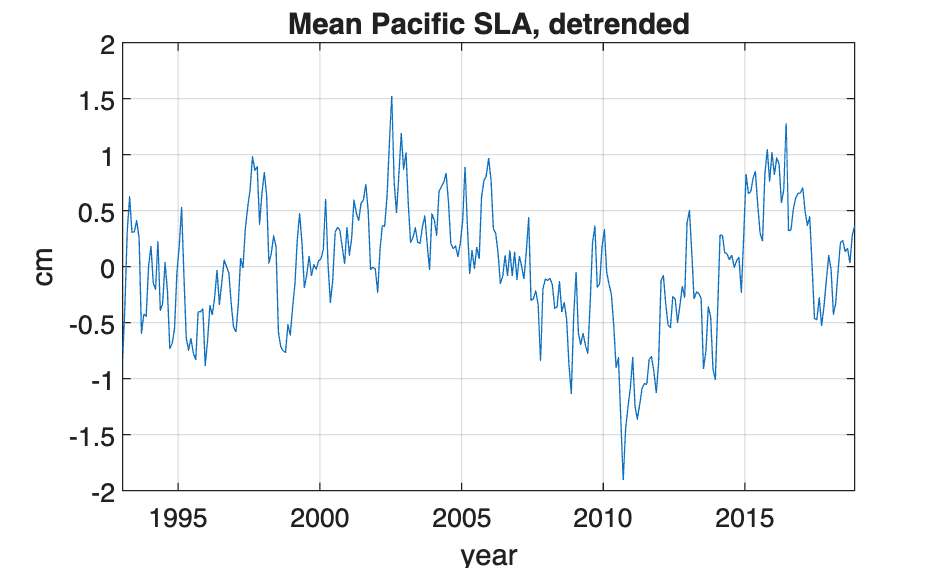

sla_det = sla_avg - polyval(P,tt);
figure (3)
clf
%plot(ALT.t,sla_det*100)
plot(ALT.t,detrend(sla_det,2)*100)

ylabel('cm')
xlabel('year')
title('Mean Pacific SLA, detrended')
grid on

## Compare with ONI, check for serial correlation

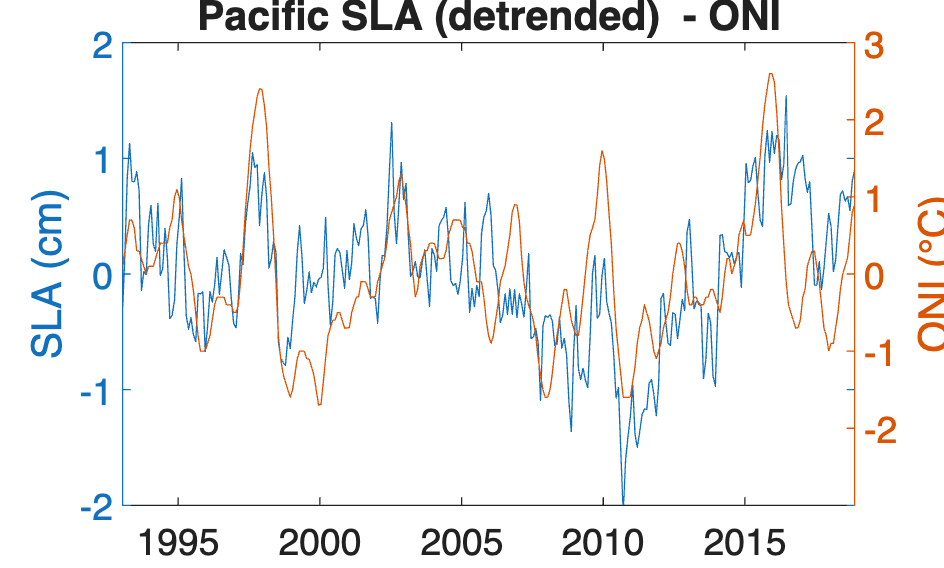

figure (4)
clf
[hAx,hLine1,hLine2] = plotyy(ALT.t,sla_det*100,ALT.t,ONI);
xlabel('year')
ylabel(hAx(1),'SLA (cm)') % left y-axis
ylabel(hAx(2),'ONI (°C)') % right y-axis
set(hAx(1),'FontSize',14)
set(hAx(2),'FontSize',14)
set(hAx(1),'ylim',[-2 2])
set(hAx(2),'ylim',[-3 3])
title('Pacific SLA (detrended)  - ONI')

[r,P] = corr(sla_det,ONI);
formatspec = 'r = %.2f, p-value = %.2f';
display(sprintf(formatspec,r,P))

r = 0.55, p-value = 0.00


## Compare with Global Mean Sea Level (GMSL.mat)

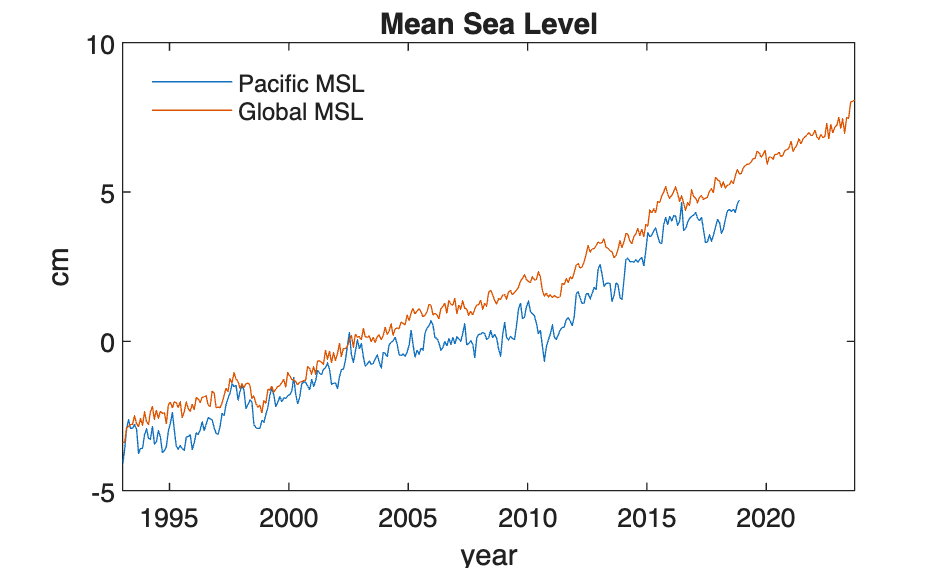

load GMSL
figure (5)
clf
plot(ALT.t,sla_avg*100,GMSL.t,GMSL.sl*100)
ylabel('cm')
xlabel('year')
legend('Pacific MSL','Global MSL','Location','northwest')
legend('boxoff')
title('Mean Sea Level')

## Compare with Global Mean Sea Level (GMSL.mat) - detrended

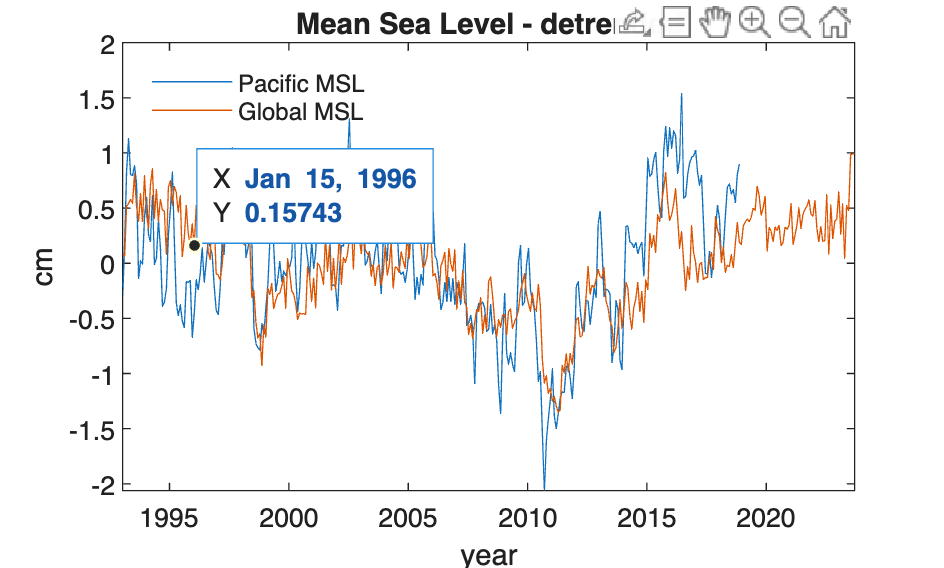

figure (6)
clf
plot(ALT.t,sla_det*100,GMSL.t,detrend(GMSL.sl)*100)
ylabel('cm')
xlabel('year')
legend('Pacific MSL','Global MSL','Location','northwest')
legend('boxoff')
title('Mean Sea Level - detrended')